# MATLAB fundamentals for EM-based applications

## Compact layout and shortcuts

For beginners, you can join online corses: [MATLAB and Simulink Training (mathworks.com)](https://matlabacademy.mathworks.com/), which is free for TU Delft student.

### Clean coding style

To make the codes more readable, we could add spaces between symbols:

% Crowded style
x=sind(30)+1e9+2.^2; 

% Clean style
x = sind(30) + 1e9 + 2^2; 

### Function feature

To avoid repeated codes, we could use separate functions. For a short script, we can use in-script functions, which are put at the end of the script:

% Main code....
% ...
% M = cal_val(1, 2, 3)
% ...

% function output = cal_val(x, y, z)
%  output = x + y + z;
% end

However, for a very long script, putting functions at the end would be inconvenient. Instead, we can write separate routines and call them in the main script:

% Main code...
... 
% We could create a new script in current directory called cal_val.m:
M = cal_val(1, 2, 3)

M = 6

### Comment feature

When a script becomes longer and longer, it will be harder to search for and maintain a specific part in the script. In such a case, we can break each section by using double ***%%***  and write comments after them. For each line, a single ***%*** can be used after the ending semicolon. For instance:

%% Parameters
c = 3e8; % speed of light
f = 8e9; % frequency
... 
%% frequency dependent parameters
lam = c / f;
...
%% Calculation
M = cal_val(1, 2, 3);
...

### Useful Shortcuts

Try to use the following shortcuts to improve your coding efficiency. 

Run                    F5               Comment           Ctrl+R

Run next line     F10             Uncomment        Ctrl+T

Stop                  shift+F5       Smart indent       Ctrl+I

### Report feature

Moreover, for a cooperative coding scenario, if you made some changes or want your colleagues to take over your work, it would be convenient to use the ***TODO Report*** feature:

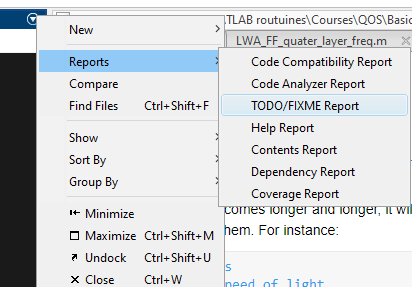                 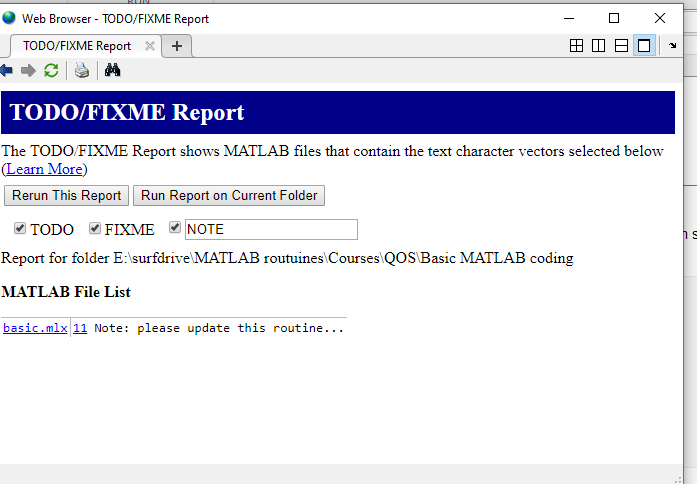

To create such a report, you just need to type* "****Note****"* in a comment:

% Note: please update this routine...

***Dependency Report*** could also be useful when you want to find all dependency for a parameter.

### Online support

You can find more instructions online: [MATLAB and Simulink Training (mathworks.com)](https://matlabacademy.mathworks.com/)

Recommanded corse: "MATLAB Programming Techniques" - free for TU Delft students

## Parametric sweep of parameters

In a EM application, it is common to plot one parameter as a function another parameter. To do so, one should run the whole or a part of the script repeatedly while changing the internal parameters at the same time. Therefore, it would be wise to define parameters parametrically and let the script run automatically. For a parameter that needs to be changed, we commonly use the following two deifinitions:

% Given step
f_s = 10; % Frequency: GHz
f_e = 50;
df  = 10; % Step
f = (f_s:df:f_e)*1e9  

f = 1.0e+10 *

    1.0000    2.0000    3.0000    4.0000    5.0000


% Specify the numebr of point
th_s = eps % Theta: radian,  to degree: theta * 180 / pi, eps: very small value

th_s = 2.2204e-16

th_e = pi / 2; 
num_th = 10; % number of point
theta = linspace(th_s, th_e, num_th) 

theta =     0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708


After that, we can use *for/parfor* loop to run the script automatically. First we need to pre-allocate memory for parameters, and then we can put them in the loop:

% Sweep frequency
% Pre-allocate memory for a parameter to improve the speed. There are two
% functions: "length" and "size"
lam_sweep = zeros(length(f));   % 1D vector
lam_sweep = zeros(size(f));     % 2D matrix

for ii = 1:length(f) % Or "parfor" for parallel calculation which increases the speed a lot
    lam_sweep(ii) = 3e8 ./ f(ii)
end

lam_sweep =     0.0300         0         0         0         0


lam_sweep =     0.0300    0.0150         0         0         0


lam_sweep =     0.0300    0.0150    0.0100         0         0


lam_sweep =     0.0300    0.0150    0.0100    0.0075         0


lam_sweep =     0.0300    0.0150    0.0100    0.0075    0.0060


## Coordinate systems 

There are three widely used coordinate systems: cartesian, cylindrical, and spherical systems. In a far field calculation, spherical system is commonly used and its definition is shown below:

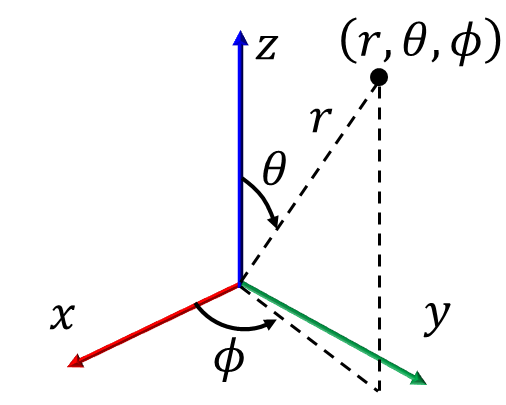

As is shown, a point in spherical system can be defined by $\left(r,\theta ,\phi \;\right)$, where $r$ is the radial distance between the origin and the point, $\theta$ is from $+\hat{z}$ to the $\textrm{xy}$ plane, and $\phi$ is from $+\hat{x}$ to $+\hat{y}$. To cover the whole spherial area, $\theta \in \left\lbrack 0,\pi \right\rbrack$, $\phi \in \left\lbrack 0,2\pi \right\rbrack$. If we only consider the upper hemisphere, we can define $\theta \in \left\lbrack 0,\pi /2\right\rbrack$. In MATLAB, if we want to evaluate and plot each point on a hemisphere, it would be convenient to define $\left(\theta ,\phi \right)$ as a grid which can be done by using ***meshgrid***: 

%% Evaluate each point on the upper hemisphere
num_th = 10;
num_ph = 20;
theta = linspace(eps, pi / 2, num_th) % radian

theta =     0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708


phi   = linspace(eps, pi * 2, num_ph)

phi =     0.0000    0.3307    0.6614    0.9921    1.3228    1.6535    1.9842    2.3149    2.6456    2.9762    3.3069    3.6376    3.9683    4.2990    4.6297    4.9604    5.2911    5.6218    5.9525    6.2832


[TH, PH] = meshgrid(theta, phi) 

TH =     0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708
    0.0000    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.

PH =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307    0.3307
    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614    0.6614
    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921    0.9921
    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228    1.3228
    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535    1.6535
    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842    1.9842
    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149    2.3149
    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456    2.6456
    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2.9762    2.

% [X, Y] = meshgrid(x, y) returns 2D grid coordinates based on the coordinates contained in vectors x and y.
% X is a matrix where each row is a copy of x, and Y is a matrix where each column is a copy of y. 


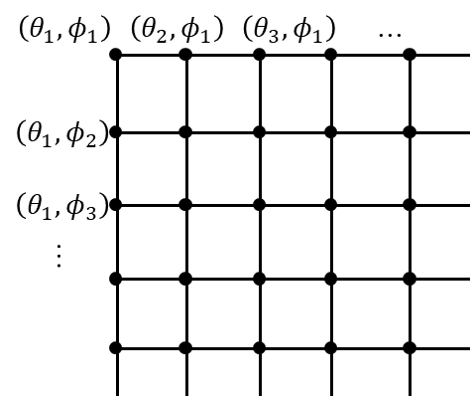

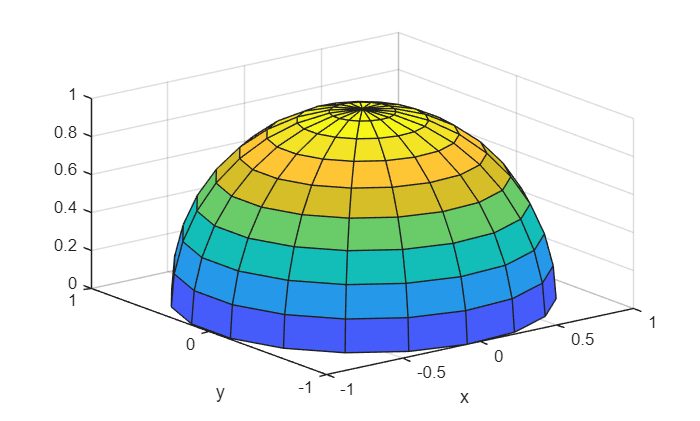

% Each point (x,y,z) on the hemisphere, for numerical calculation, we need
% to convert spherical parameters to catesian values.
R = 1; % radius of 1 m
Hemi_sph_x = R * sin(TH) .* cos(PH); % X: note that X,Y,Z are non-uniform parameters while TH, PH are uniform 
Hemi_sph_y = R * sin(TH) .* sin(PH); % Y
Hemi_sph_z = R * cos(TH);            % Z

% Plot the surface
figure;
surface(Hemi_sph_x, Hemi_sph_y, Hemi_sph_z)
xlabel('x')
ylabel('y')
grid on
view(3)

### Coordinate system conversions

Sometimes it would be more convenient to convert other coordinate systems to cartesian system (or vice versa)

**Spherical and cartesian**

% Spherical to catesian
X = R .* sin(TH) .* cos(PH);
Y = R .* sin(TH) .* sin(PH);
Z = R .* cos(TH);
% Cartesian to spherical
PH = atan(Y ./ X); % or atan2(Y, X)
TH = asin( sqrt(X.^2 + Y.^2) / R );
R  = Z ./ cos(TH);
% Example
% card_2_sphere.m

#### 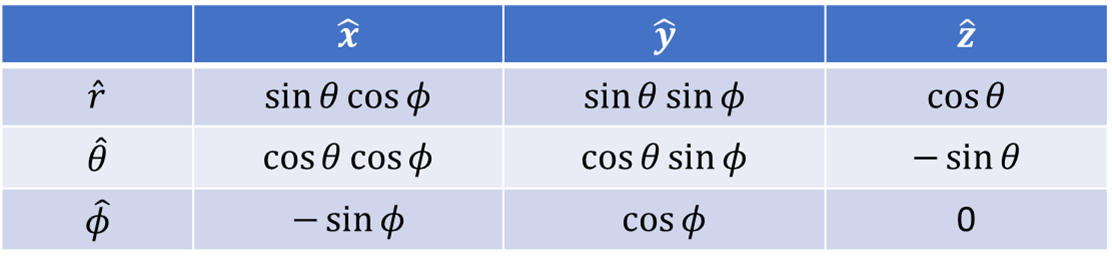

**Cylindrical  and cartesian**

% Cylindrical to catesian
Rho = 1;
X = Rho .* cos(PH);
Y = Rho .* sin(PH);
% Cartesian to cylindrical
PH = atan(Y ./ X);
Rho = X ./ cos(PH);

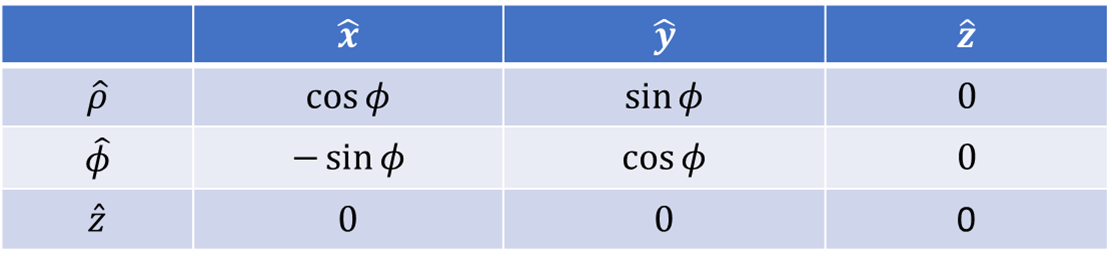

## Vector operation

In MATLAB, we can perform dot/cross product easily using build-in functions so that the operation between parameters will be more intuitive. But before doing so, we should define parameters as a 3D vector.

### 3D vector

For instance, for a point $\vec{Q} =Q_x \hat{x} +Q_y \hat{y} +Q_z \hat{z}$ on a sphere with the radius of $R$, we can define it as follows:

num_th = 5;
num_ph = 10;
theta = linspace(eps, pi / 2, num_th); % radian, to degree: theta * 180 / pi
phi   = linspace(eps, pi * 2, num_ph);
[TH, PH] = meshgrid(theta, phi);

R = 1;
% Pre-allocate
Q = zeros([size(TH), 3]); % 3D, Qx/y/z are evaluated in cartesian coordinate
Q(:,:,1) = R * sin(TH) .* cos(PH); % Qx
Q(:,:,2) = R * sin(TH) .* sin(PH); % Qy
Q(:,:,3) = R * cos(TH) % Qz

Q = Q(:,:,1) =

    0.0000    0.3827    0.7071    0.9239    1.0000
    0.0000    0.2932    0.5417    0.7077    0.7660
    0.0000    0.0665    0.1228    0.1604    0.1736
   -0.0000   -0.1913   -0.3536   -0.4619   -0.5000
   -0.0000   -0.3596   -0.6645   -0.8682   -0.9397
   -0.0000   -0.3596   -0.6645   -0.8682   -0.9397
   -0.0000   -0.1913   -0.3536   -0.4619   -0.5000
    0.0000    0.0665    0.1228    0.1604    0.1736
    0.0000    0.2932    0.5417    0.7077    0.7660
    0.0000    0.3827    0.7071    0.9239    1.0000


Q(:,:,2) =

    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.2460    0.4545    0.5939    0.6428
    0.0000    0.3769    0.6964    0.9098    0.9848
    0.0000    0.3314    0.6124    0.8001    0.8660
    0.0000    0.1309    0.2418    0.3160    0.3420
   -0.0000   -0.1309   -0.2418   -0.3160   -0.3420
   -0.0000   -0.3314   -0.6124   -0.8001   -0.8660
   -0.0000   -0.3769   -0.6964   -0.9098   -0.9848
   -0.0000   -0.2460   -0.4545   -0.5939   -0.6428
 

And then we can define a normal vector $\hat{n}$ points towards $+\hat{z\;}$ direction:

% Pre-allocate
n = zeros([size(TH), 3]); 
n(:,:,3) = ones(size(TH)) % Qz

n = n(:,:,1) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


n(:,:,2) =

     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


n(:,:,3) =

     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


### Dot product

To calculate the dot product between $\vec{Q}$ and $\hat{n}$:


$$\vec{Q} \cdot \hat{n} =Q_x n_x +Q_y n_y +Q_z n_z$$


we could simply use the ***sum*** function in 3D:

% Dot product
Dot_prod = sum(Q .* n, 3) % In this case is Qz 

Dot_prod =     1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000


Q(:,:,3) % Qz

ans =     1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000
    1.0000    0.9239    0.7071    0.3827    0.0000


### Cross product

We can use ***cross*** function to perform the corss production $\vec{Q} \times \hat{n}$:

% Cross product
Cross_prod = cross(Q, n, 3) 

Cross_prod = Cross_prod(:,:,1) =

    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.2460    0.4545    0.5939    0.6428
    0.0000    0.3769    0.6964    0.9098    0.9848
    0.0000    0.3314    0.6124    0.8001    0.8660
    0.0000    0.1309    0.2418    0.3160    0.3420
   -0.0000   -0.1309   -0.2418   -0.3160   -0.3420
   -0.0000   -0.3314   -0.6124   -0.8001   -0.8660
   -0.0000   -0.3769   -0.6964   -0.9098   -0.9848
   -0.0000   -0.2460   -0.4545   -0.5939   -0.6428
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


Cross_prod(:,:,2) =

   -0.0000   -0.3827   -0.7071   -0.9239   -1.0000
   -0.0000   -0.2932   -0.5417   -0.7077   -0.7660
   -0.0000   -0.0665   -0.1228   -0.1604   -0.1736
    0.0000    0.1913    0.3536    0.4619    0.5000
    0.0000    0.3596    0.6645    0.8682    0.9397
    0.0000    0.3596    0.6645    0.8682    0.9397
    0.0000    0.1913    0.3536    0.4619    0.5000
   -0.0000   -0.0665   -0.1228   -0.1604   -0.1736
   -0.0000   -0.2932   -0

You can validate the results by calculating them on paper.

## Integral operation

Integral operation is quite often used in an EM application, for example, when calculating directivity or power. Before introducing MATLAB implementation, let's first take a look at the theoretical knowledge of integral.

### Line integral

For a curve $C$ and a scalar function $f\left(\theta \right),\;$its line integral can be represented as follows: 


$$\int_C f\left(\theta \right)d\theta =\int_0^{\max \left(\theta \right)} f\left(\theta \right)d\theta$$


For example, for $f\left(\theta \right)=\sin \theta$, one can first define it in MATLAB as:

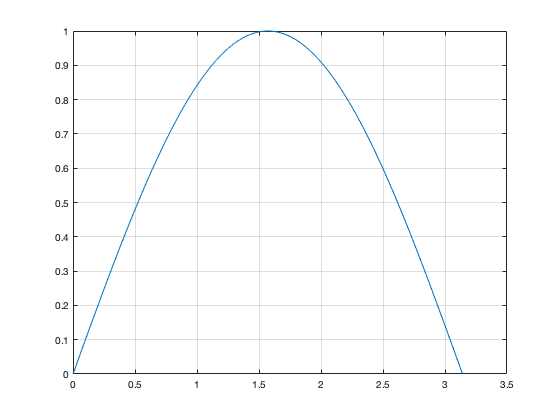

num_th = 200;
theta = linspace(0, pi, num_th);
y = sin(theta);

figure
plot(theta, y)
grid on

To calculate the integral, one can approximate the curve by using rectangles with infinitesimal width. 

               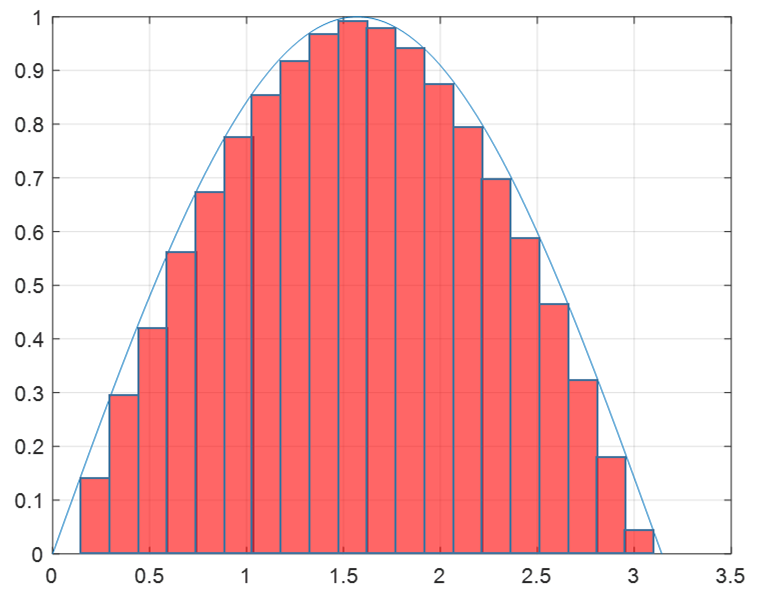

Accordingly, the integral will become a summation:


$$\int_0^{\max \left(\theta \right)} f\left(\theta \right)d\theta =\sum_0^{\max \left(\theta \right)} f\left(\theta \right)d\theta$$


In MATLAB, as long as we define $\theta$ with a relatively small spacing, the integral can be evaluated by simply summing the integrand:

dth = theta(2) - theta(1); 
Int = sum(y) * dth

Int = 2.0000

% In a integral, it is important to keep uniform spacing. The accuracy will increase if we increase num_th.

### Surface integral

In an EM application, a surface integral is more frequently used than a line integral. For a surface $S$ and a scalar function $f\left(\theta ,\phi \right)$, its surface integral becomes:


$$\int \int f\left(\theta ,\phi \right)\textrm{dS}=\int_0^{2\pi } \int_0^{\max \left(\theta \right)\;} f\left(\theta ,\phi \right)\left|\frac{\partial \vec{Q} }{\partial \theta \;}\times \frac{\partial \vec{Q} }{\partial \phi \;\;}\right|d\theta d\phi$$


where $\vec{Q} =Q_x \hat{x} +Q_y \hat{y} +Q_z \hat{z}$ is a point on the surface. Specially, when the surface is a sphere, $\left|\frac{\partial \vec{Q} }{\partial \theta \;}\times \frac{\partial \vec{Q} }{\partial \phi \;\;}\right|$ can be expressed analytically as: $R^2 \;\sin \theta$. Therefore, a useful expression can be introduced:


$$\int_0^{2\pi } \int_0^{\max \left(\theta \right)\;} f\left(\theta ,\phi \right)R^2 \;\sin \theta d\theta d\phi$$


To implement a surface integral in MATLAB, there are several steps. Here let's consider a constant function $f\left(\theta ,\phi \right)=1$on a sphere with radius $R$. Then its area can be calculated by using the surface integral:

% Spherical parameters defined as meshgrid
num_th = 200;
num_ph = 361;
theta = linspace(eps, pi, num_th); 
phi   = linspace(eps, pi * 2, num_ph); 
dth = theta(2) - theta(1);
dph = phi(2) - phi(1);
[TH, PH] = meshgrid(theta, phi);

% Sphere radius
R = 1; 
% integrand
integrand = 1;
% Surface integral: area of the sphere/ solid angle of a sphere
Result = sum( sum( integrand * R^2 .* sin(TH) ) ) * dth * dph % close to 4*pi

Result = 12.6010

For vector integrands, the formula includes a dot product:


$$\int_0^{2\pi } \int_0^{\max \left(\theta \right)\;} \vec{f} \left(\theta ,\phi \right){\cdot \hat{n} \;R}^2 \;\sin \theta d\theta d\phi$$


where $\hat{n}$ is the unit normal vector of the surface.

More detail can be found in my [thesis](https://repository.tudelft.nl/islandora/object/uuid%3A997558e6-7f32-493a-9f84-57895636db28): Section 2.1.2, 2.1.3, Appendix A.2

## Plot results

There are several functions that can be used to show results.

### 2D line results

For 2D line results, we can use "***plot"*** function:

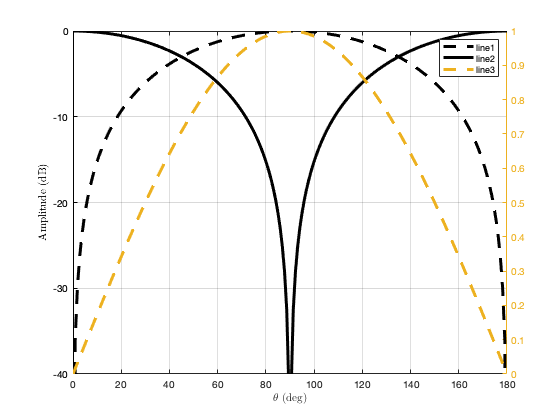

num_th = 200;
num_ph = 361;
theta = linspace(eps, pi, num_th); 
phi   = linspace(eps, pi * 2, num_ph);
[TH, PH] = meshgrid(theta, phi);

figure
% Plot line results, first input for x axis while second input for y axis.
% You can change the line properties by adding extra specs, or directly
% open the "property" in the figure
y1 = plot(theta * 180 / pi, 20*log10( sin(TH(1,:)) ) - max(max( 20*log10( sin(TH(1,:)) ))), 'Color','k',"LineStyle",'--','LineWidth', 3);
% Keep in mind that for amplitude we always use dB and limit it with
% dynamic range of 40 dB
grid on %Show grids
xlim([0, 180]) % x limit
ylim([-40, 0])  % y limit
xticks([0:20:180]); % define x-ticks 
yticks([-40:10:0]); % define y-ticks 
xlabel('$\theta$ (deg)','Interpreter','latex') % Latex syntax
ylabel('Amplitude (dB)','Interpreter','latex') % Latex syntax
% Add more lines
hold on
y2 = plot(theta * 180 / pi, 20*log10( abs(cos(TH(1,:))) ) - max(max(20*log10( abs(cos(TH(1,:))) ))), 'Color','k',"LineStyle",'-','LineWidth', 3);
% Use two y axes
hold on
yyaxis right % or yyaxis left
y3 = plot(theta * 180 / pi, sin(TH(1,:)),"LineStyle",'--','LineWidth', 3);
ylim([0, 1])  % y limit

% Add legend
legend([y1, y2, y3], {'line1', 'line2', 'line3'});

% Read data from a figure
h = findobj(gca,'Type','line')

h =   3×1 Line array:

  Line    (line3)
  Line    (line2)
  Line    (line1)


x = get(h,'Xdata');
y = get(h,'Ydata');

More properties can be changed manually in the "Property Inspector". For two x/y axes, more advanced operation can be found: [Create Chart with Multiple x-Axes and y-Axes - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/creating_plots/graph-with-multiple-x-axes-and-y-axes.html).

### 3D results

To plot a 3D result, for instance, $\vec{E} \left(\theta ,\phi \;\right)=\cos^{2\;} \theta \;\left(\sin \phi \;\hat{\theta \;} +\cos \phi \hat{\phi} \right)$, we can use "***surface"*** function:

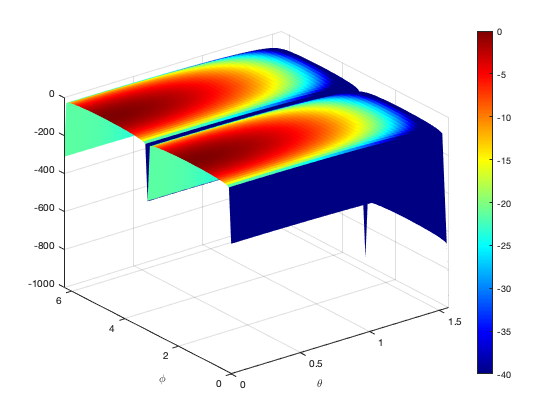

% For a electric field, we always define the upper hemisphere
num_th = 50;
num_ph = 75;
theta = linspace(eps, pi / 2, num_th); 
phi   = linspace(eps, pi * 2, num_ph); 
[TH, PH] = meshgrid(theta, phi);

% Defin the electric field
E_th = cos(TH).^2 .* sin(PH);
E_ph = cos(TH).^2 .* cos(PH);
E_r  = zeros(size(TH));

% To plot a 3D elcetric field, we use surface function. 
% We have two types of representation. First is to directly use TH and PH 
figure;
surface(TH, PH, 20*log10(abs(E_th)) - max(max(20*log10(abs(E_th)))), 'linestyle', 'none') % When the number of point increases, it would be better to hide lines
grid on
xlabel('\theta')
ylabel('\phi')
colormap('jet')
colorbar
caxis([-40, 0]) 
view(-37.5,30) % Change the view angle [Az,El]

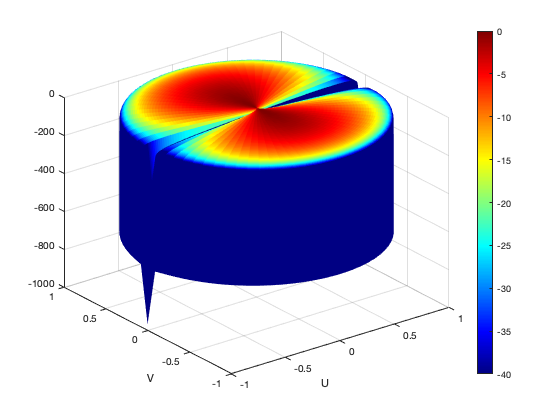

% The mostly used representation is UV representation
U = sin(TH) .* cos(PH);
V = sin(TH) .* sin(PH);
figure;
surface(U, V, 20*log10(abs(E_th)) - max(max(20*log10(abs(E_th)))), 'linestyle', 'none') % When the number of point increases, it would be better to hide lines
xlabel('U')
ylabel('V')
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 
view(-37.5,30) % Change the view angle [Az,El]

% Find data from a surface
h = findobj(gca,'Type','surface')

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: 'none'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [75×50 double]
           YData: [75×50 double]
           ZData: [75×50 double]
           CData: [75×50 double]

  Show all properties


x = get(h,'Xdata') ;
y = get(h,'Ydata') ;
z = get(h,'Zdata') ;

To make the surface smoother without re-running the code, we can interpolate current values by using "***interp2***" or "***griddata***":

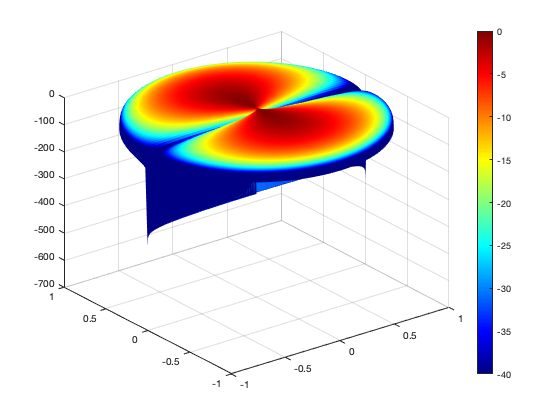

th_interp = linspace(eps, pi / 2, num_th * 2);
ph_interp = linspace(eps, pi * 2, num_ph * 3);
[TH_interp, PH_interp] = meshgrid(th_interp, ph_interp);
E_interp_1 = interp2(TH, PH, E_th, TH_interp, PH_interp, 'spline');  % interpolation methods: linear, nearest, cubic, and etc.
E_interp_2 = griddata(TH, PH, E_th, TH_interp, PH_interp, 'linear'); % interpolation methods: linear, nearest, cubic, and etc.

% Interp2 runs much faster than griddata and the 'spline' is a better method
% which is not included in griddata. However, interp2 can only be used for
% input that are linearly defined by meshgrid. When TH or PH are
% non-linear, we can only use griddata.

figure;
surface(sin(TH_interp) .* cos(PH_interp), sin(TH_interp) .* sin(PH_interp), 20*log10(abs(E_interp_1)) - max(max(20*log10(abs(E_interp_1)))), 'linestyle', 'none') 
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 
view(-37.5,30) % Change the view angle [Az,El]

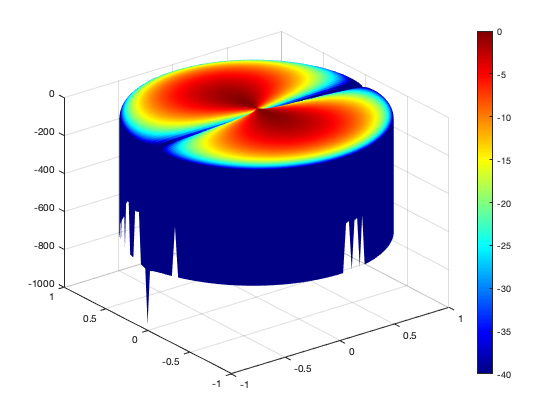

figure;
surface(sin(TH_interp) .* cos(PH_interp), sin(TH_interp) .* sin(PH_interp), 20*log10(abs(E_interp_2)) - max(max(20*log10(abs(E_interp_2)))), 'linestyle', 'none') 
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 
view(-37.5,30) % Change the view angle [Az,El]

## Exercises

Consider the far field of an antenna: $\vec{E} \left(\theta ,\phi \;\right)=\cos^{2\;} \theta \;\left(\sin \phi \;\hat{\theta \;} +\cos \phi \hat{\phi} \right)$. Try to solve the following questions:

### Conversion between different coordinate systems

We have known the expression of the far field with spherical coordinate. For further calculation, we can convert it to cartesian cooridnate. Creat a routine that can be used later:

%% TH/PH
num_th = 200;
num_ph = 361;
theta = linspace(eps, pi / 2, num_th); 
phi   = linspace(eps, pi * 2, num_ph); 
[TH, PH] = meshgrid(theta, phi);

% Defin the far field
E_th = cos(TH).^2 .* sin(PH);
E_ph = cos(TH).^2 .* cos(PH);
E_r  = zeros(size(TH));
E_xyz = sph_2_card_loop( E_th , E_ph , E_r , TH , PH );
E_x = E_xyz(:,:,1);
E_y = E_xyz(:,:,2);
E_z = E_xyz(:,:,3);

### Plot the far field 

Plot each component of the far field, $E_x$, $E_y$, $E_z$.

(1) Plot $E_y$ in $\phi =0^{\circ \;}$ and ${90}^{\circ }$ planes (referred to as main planes)

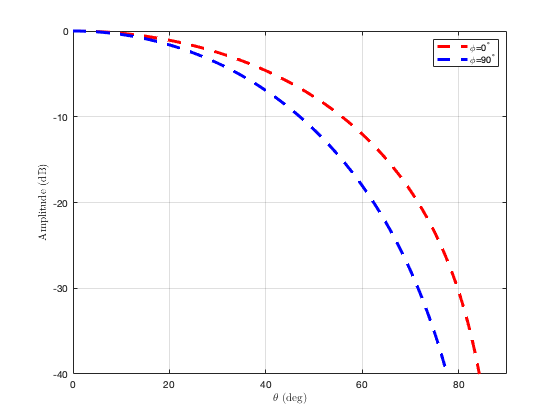

figure
y1 = plot(theta * 180 / pi, 20*log10( E_y(1,:) ) - max(max( 20*log10( E_y(:,:) ))), 'Color','r',"LineStyle",'--','LineWidth', 3);
hold on
y2 = plot(theta * 180 / pi, 20*log10( E_y(91,:) ) - max(max( 20*log10( E_y(:,:) ))), 'Color','b',"LineStyle",'--','LineWidth', 3);
grid on %Show grids
xlim([0, 90]) % x limit
ylim([-40, 0])  % y limit
xticks([0:20:180]); % define x-ticks 
yticks([-40:10:0]); % define y-ticks 
xlabel('$\theta$ (deg)','Interpreter','latex') % Latex syntax
ylabel('Amplitude (dB)','Interpreter','latex') % Latex syntax
% Add legend
legend([y1, y2], {'\phi=0^\circ', '\phi=90^\circ'});

(2) Plot $E_x$, $E_y$, $E_z$ in UV grid

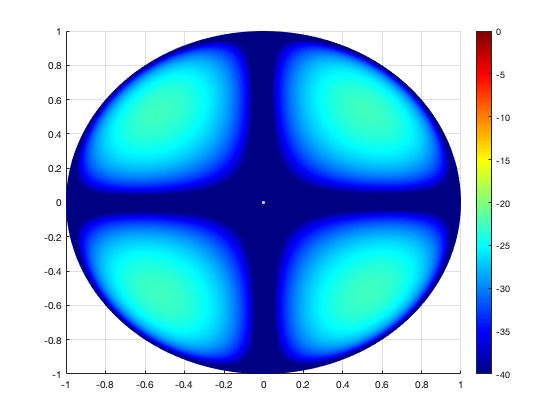

U = sin(TH) .* cos(PH);
V = sin(TH) .* sin(PH);
figure;
surface(U, V, 20*log10(abs(E_x)) - max(max(20*log10(abs(E_y)))), 'linestyle', 'none') 
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 

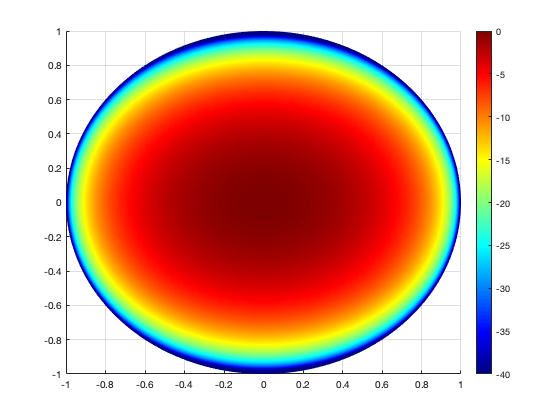

figure;
surface(U, V, 20*log10(abs(E_y)) - max(max(20*log10(abs(E_y)))), 'linestyle', 'none') 
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 

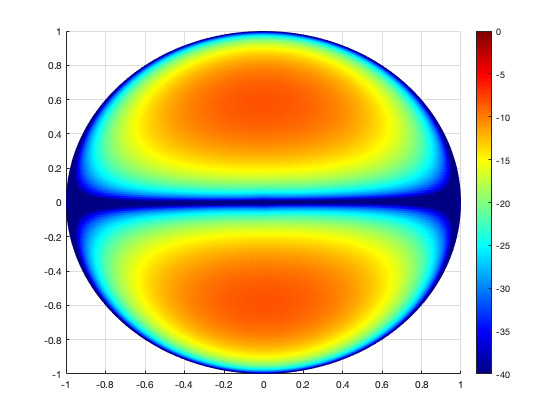

figure;
surface(U, V, 20*log10(abs(E_z)) - max(max(20*log10(abs(E_y)))), 'linestyle', 'none') 
grid on
colormap('jet')
colorbar
caxis([-40, 0]) 

### Vectorial product

Assume the propagation unit vector $\hat{k} =\hat{r}$.

r_vec = zeros([size(TH), 3]);
r_vec(:,:,1) = sin(TH) .* cos(PH);
r_vec(:,:,2) = sin(TH) .* sin(PH);
r_vec(:,:,3) = cos(TH);

(1) Use the cross product to calculate the magnetic field: $\vec{H} =\frac{1}{\zeta_0 \;}\hat{k} \times \vec{E}$.

zeta_0 = 120 *pi;
H_xyz = 1 / zeta_0* cross(r_vec, E_xyz, 3);

(2) Obtain the poynting vector:$\vec{S} =\frac{1}{2}\textrm{Re}\left(\vec{E} \times \vec{H^* } \right)$. You can validate the amplitude by using the expression: $\left|\vec{S} \right|=\frac{{\left|\vec{E} \right|}^2 }{2\zeta_0 \;}$.

S_xyz = 0.5 * real( cross(E_xyz , conj(H_xyz), 3) );
validation = sqrt( sum(S_xyz .* conj(S_xyz), 3) ) - sum(E_xyz .* conj(E_xyz), 3) / 2 / zeta_0;

(3) Try dot product between $\vec{E}$/$\vec{H}$ and $\vec{S}$.

result = sum(E_xyz .* S_xyz, 3);

### Intergal

Evaluate the power captured by a far-field sphere with a radius of 1m


$$P=\int_0^{2\pi } \int_0^{\frac{\pi }{2}} \vec{S} \cdot \hat{r} \;R^2 \;\sin \theta \;d\theta d\phi$$


R = 1;
dth = abs( TH(1,1) - TH(1,2) ) ;
dph = abs( PH(1,1) - PH(2,1) ) ;

integrand =  sum(S_xyz .* r_vec, 3) * (R^2) .* sin(TH);
Prad_ant = sum(sum( integrand )) * dth * dph;